# Optimized Output Feedback using LQG

% Masses are in KG and length in CM.
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 10;

% Substituting given values in the system to check controllability

A = [0 1      0             0      0             0;
     0 0 (-m1*g/M)          0 (-m2*g/M)          0; 
     0 0      0             1      0             0;
     0 0 (-(M+m1)*g)/(M*l1) 0 (-m2*g)/(M*l1)     0;
     0 0      0             0      0             1;
     0 0 -(m1*g)/(M*l2)     0 (-g*(M+m2))/(M*l2) 0]

A =          0    1.0000         0         0         0         0
         0         0   -1.0000         0   -1.0000         0
         0         0         0    1.0000         0         0
         0         0   -0.5500         0   -0.0500         0
         0         0         0         0         0    1.0000
         0         0   -0.1000         0   -1.1000         0



B = [     0; 
        1/M; 
          0; 
    1/(M*(l1)); 
          0; 
    1/(M*l2)]

B = 1.0e-03 *

         0
    1.0000
         0
    0.0500
         0
    0.1000



C1 = [1 0 0 0 0 0]                                        

C1 =      1     0     0     0     0     0


C3 = [1 0 0 0 0 0; 0 0 0 0 1 0]             

C3 =      1     0     0     0     0     0
     0     0     0     0     1     0


C4 = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]

C4 =      1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0



D = 0

D = 0


% Taking initial Q condition for Luenberger observer
Q = [100  0   0  0  0   0;
         0   80   0  0  0   0;
         0    0 200  0  0   0;
         0    0   0 80  0   0;
         0    0   0  0 50   0;
         0    0   0  0  0 300];
R = 0.0005

R = 5.0000e-04


% Considering initial observer values for later comaprison
Y_init = [0.5; 0; 5; 0; 5; 0; 0; 0; 0; 0; 0; 0]

Y_init =     0.5000
         0
    5.0000
         0
    5.0000
         0
         0
         0
         0
         0



% Observability can be calculated using in-built LQR function.
K = lqr(A,B,Q,R)

K = 1.0e+03 *

    0.4472    1.1258    0.1113   -0.6999    0.2695   -0.2971



% Taking system and measurement noise
Vd = 1*eye(6)

Vd =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


Vn = 1

Vn = 1


% Computing gain matrix based on new noise parameters
K1=lqr(A',C1',Vd,Vn)'

K1 =     3.0456
    4.1377
   -1.0739
    1.0494
   -1.1201
    0.3287


K3=lqr(A',C3',Vd,Vn)' 

K3 =     2.7464   -0.0230
    3.2715   -0.3503
   -1.4411   -0.2600
    0.6106   -0.0660
   -0.0230    1.3272
    0.2568    0.3810


K4=lqr(A',C4',Vd,Vn)' 

K4 =     2.0609   -0.1557   -0.0679
    1.6380   -0.7067   -0.5194
   -0.1557    1.4615   -0.0392
    0.1609    0.5809   -0.0399
   -0.0679   -0.0392    1.3087
    0.2969   -0.0580    0.3595


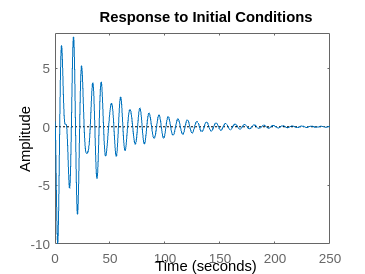


% New state-space based on C1
sys_c1 = ss([(A-B*K) B*K; zeros(size(A)) (A-K1*C1)], [B;zeros(size(B))],[C1 zeros(size(C1))], D);
figure
initial(sys_C1,Y_init)

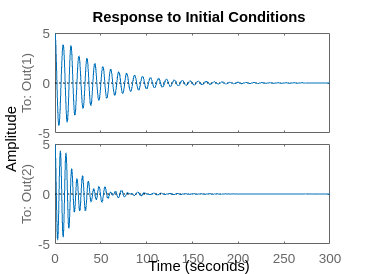


% New state-space based on C3
sys_c3 = ss([(A-B*K) B*K; zeros(size(A)) (A-K3*C3)], [B;zeros(size(B))],[C3 zeros(size(C3))], D);
figure
initial(sys_C3,Y_init)

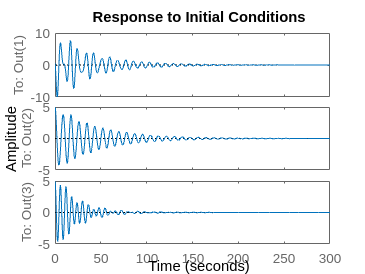


% New state-space based on C4
sys_c4 = ss([(A-B*K) B*K; zeros(size(A)) (A-K4*C4)], [B;zeros(size(B))],[C4 zeros(size(C4))], D);
figure
initial(sys_C4,Y_init)